# Color transfer between images

## Color transfer will transfer the color tone from the source image to the target image.

Step 1: Input images are a source and a target image.  Display both images.

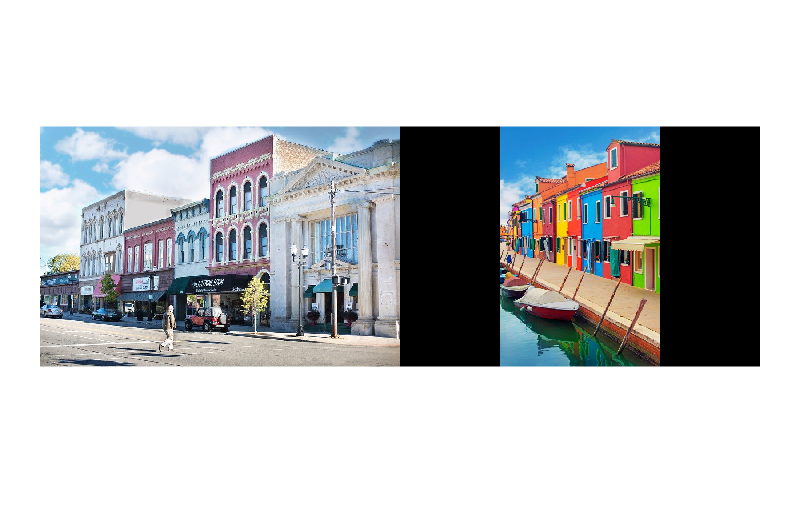

% Source img
block_img = imread('city_block1.png');

% Target img
colorful_img = imread('colorful_town1.png');
[r,c,ch] = size(colorful_img);

montage({block_img, colorful_img});

Step 2: Convert RGB to lαβ color space.  Images have size [m n 3].  You can use function "reshape" to change the size to [m*n  3]. So that we can multiply with other matrices.

% Reshape (get matrix size [m*n 3])
% ** Aj said that max will replace the value when it's 0, then it will set a
% very small number like 1/255 instead**
BLOCK = reshape(max(im2double(block_img), 1/255), [], 3);
COL = reshape(max(im2double(colorful_img), 1/255), [], 3);

% Finding lms
Block_lms = [0.3811 0.5783 0.0402; 0.1967 0.7244 0.0782; 0.0241 0.1288 0.8444] * BLOCK.';
Color_lms = [0.3811 0.5783 0.0402; 0.1967 0.7244 0.0782; 0.0241 0.1288 0.8444] * COL.';

% Finding LMS (take log to lms)
Block_LMS = log10(Block_lms);
Color_LMS = log10(Color_lms);

% Finding lαβ
Block_lab = [(1/sqrt(3)) 0 0; 0 (1/sqrt(6)) 0; 0 0 (1/sqrt(2))] ...
    * [1 1 1; 1 1 -2; 1 -1 0] * Block_LMS;
Color_lab = [(1/sqrt(3)) 0 0; 0 (1/sqrt(6)) 0; 0 0 (1/sqrt(2))] ...
    * [1 1 1; 1 1 -2; 1 -1 0] * Color_LMS;

Step 3: Compute the mean and standard deviation of each of the lαβ channels for the source and target images.

% Finding mean (μ) of each lαβ channels
Block_meanl = mean2(Block_lab(1,:));
Block_meana = mean2(Block_lab(2,:));
Block_meanb = mean2(Block_lab(3,:));

Color_meanl = mean2(Color_lab(1,:));
Color_meana = mean2(Color_lab(2,:));
Color_meanb = mean2(Color_lab(3,:));

% Finding standard deviation (σ) of each lαβ channels
Block_stdl = std2(Block_lab(1,:));
Block_stda = std2(Block_lab(2,:));
Block_stdb = std2(Block_lab(3,:));

Color_stdl = std2(Color_lab(1,:));
Color_stda = std2(Color_lab(2,:));
Color_stdb = std2(Color_lab(3,:));

Step 4: Subtract the mean of the lαβ channels of the target image from target channels.

targ_l = Color_lab(1,:) - Color_meanl;
targ_a = Color_lab(2,:) - Color_meana;
targ_b = Color_lab(3,:) - Color_meanb;

Step 5: Scale the target channels by the ratio of the standard deviation of the source divided by the standard deviation of the target, multiplied by the target channels.

targ_l = (Block_stdl / Color_stdl) * targ_l;
targ_a = (Block_stda / Color_stda) * targ_a;
targ_b = (Block_stdb / Color_stdb) * targ_b;

Step 6: Add in the means of the lαβ channels for the source.

targ_l = targ_l + Block_meanl;
targ_a = targ_a + Block_meana;
targ_b = targ_b + Block_meanb;

Step 7: Convert lαβ back to RGB color space.

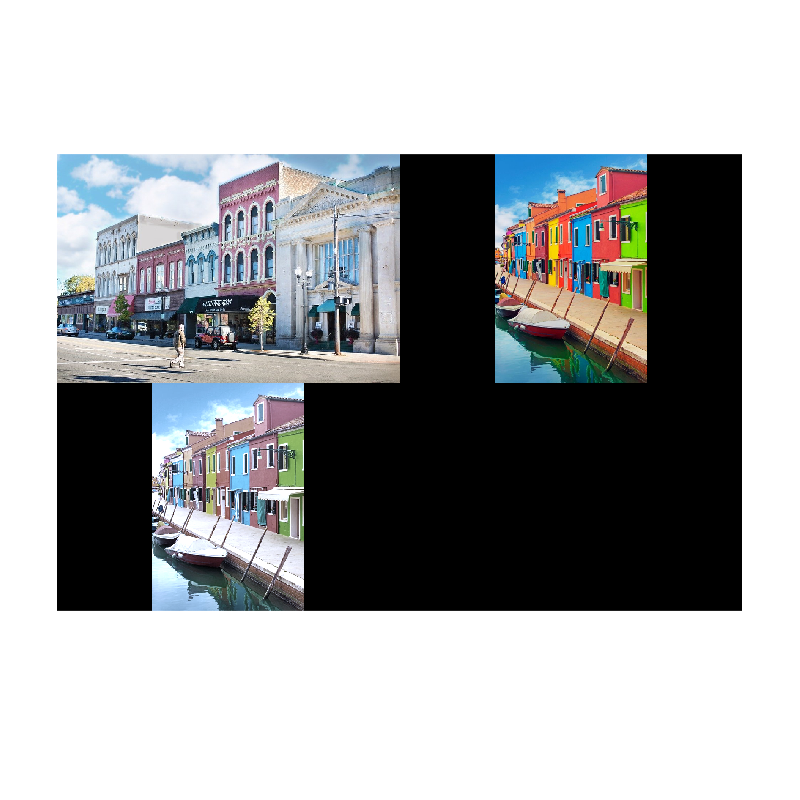

% Concat each row, row by row
targ_lab = vertcat(targ_l, targ_a, targ_b);

LMS = [1 1 1; 1 1 -1; 1 -2 0] * [(sqrt(3)/3) 0 0; 0 (sqrt(6)/6) 0; 0 0 (sqrt(2)/2)] ...
    * targ_lab;

% Invert log scale
lms = power(10,LMS);

final_rgb = [4.4679 -3.5873 0.1193; -1.2186 2.3809 -0.1624; 0.0497 -0.2439 1.2045] * lms;

% Separate each channel
R = final_rgb(1,:);
G = final_rgb(2,:);
B = final_rgb(3,:);

% Concat to RGB channels in one
final_rgb = cat(3, R, G, B);

% Reshape to match with a given size
final_rgb = reshape(final_rgb, [r c ch]);

montage({block_img, colorful_img, final_rgb});